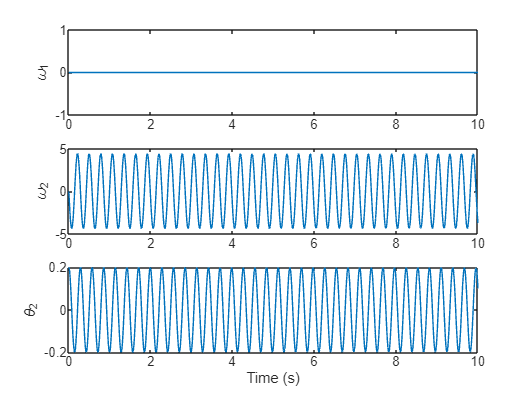

clear
clc

%% Parameters
J1 = 0.02;
J2 = 0.01;
m2 = 0.5;
Lp = 0.2;
Lr = 0.3;
g  = 9.81;

tau = 0; % constant torque input

%% Simulation time
tspan = [0 10];

%% Initial conditions [w1 w2 theta2]
x0 = [0; 0; 0.2];

%% Solve ODE
[t,x] = ode45(@(t,x)dynamics(t,x,J1,J2,m2,Lp,Lr,g,tau),tspan,x0);

w1 = x(:,1);
w2 = x(:,2);
theta2 = x(:,3);

%% Plot results
figure

subplot(3,1,1)
plot(t,w1)
ylabel('\omega_1')

subplot(3,1,2)
plot(t,w2)
ylabel('\omega_2')

subplot(3,1,3)
plot(t,theta2)
ylabel('\theta_2')
xlabel('Time (s)')